#### Ques 01(a)

syms f(eta)
eqn = diff(f,3) + f* diff(f,2) == 0;
f = odeToVectorField(eqn)

$$f = \left(\begin{array}{c} Y_{2}\\ Y_{3}\\ -Y_{1}\,Y_{3} \end{array}\right)$$

#### Ques 01(b)

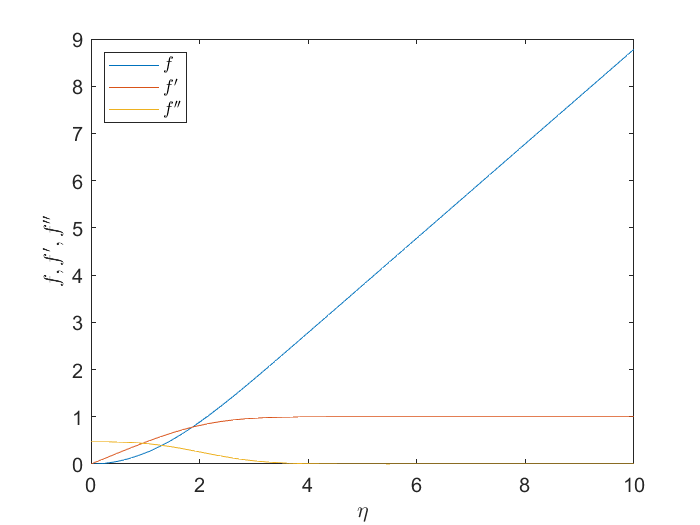

eta_end = 10;
f0 = [0; 0; 0.4696];
[eta, f] = ode45(@sysode, [0, eta_end], f0);
figure 
plot(eta, f(:,1), eta, f(:,2), eta, f(:,3));
xlim([0 10])
ylim([0 9])
xlabel('$\eta$','interpreter','latex')
ylabel('$f, f'', f''''$','interpreter','latex')
legend({'$f$', '$f''$', '$f''''$'},'interpreter','latex', 'location', 'NorthWest')
set(gca,'Fontsize',12)

#### Ques 01(c)

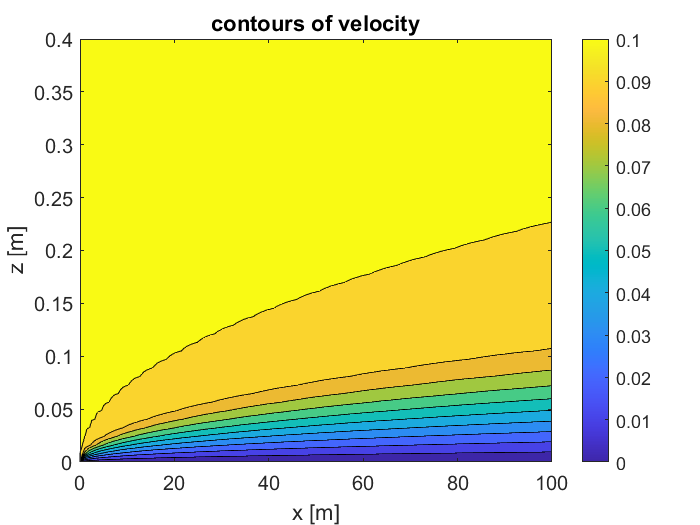

Uinfty = 0.1;
nu = 1e-6;
x = linspace(0, 100,200);
z = linspace(0, 0.8);
[X Z] = meshgrid(x, z);
% OPTION 1: Calculate u using a for-loop:
u = zeros(size(X));
for i=1:length(x)
for j=1:length(z)
Eta = Z(j,i) .* sqrt(Uinfty ./ (2 * nu * X(j,i)));
Eta = min(Eta, eta_end); % limit the value of Eta to eta_end to avoid
% NaNs in the output of interp1.
u(j, i) = Uinfty * interp1(eta, f(:,2), Eta);
end
end

% OPTION 2: Calculate u using vectorized expressions
% Eta = Z .* sqrt(Uinfty ./ (2 * nu * X));
% Eta(Eta > eta_end) = eta_end;
% u = interp1(eta, Uinfty * y(:,2), Eta);
% % plot the velocity profile
figure;
contourf(X, Z, u);
ylim([0 0.4])
xlabel('x [m]')
ylabel('z [m]')
title('contours of velocity')
colorbar
set(gca,'Fontsize',12)